**Challenge Problem:**

*Period of Anharmonic Oscillator:  We can set our mass to be = 1*

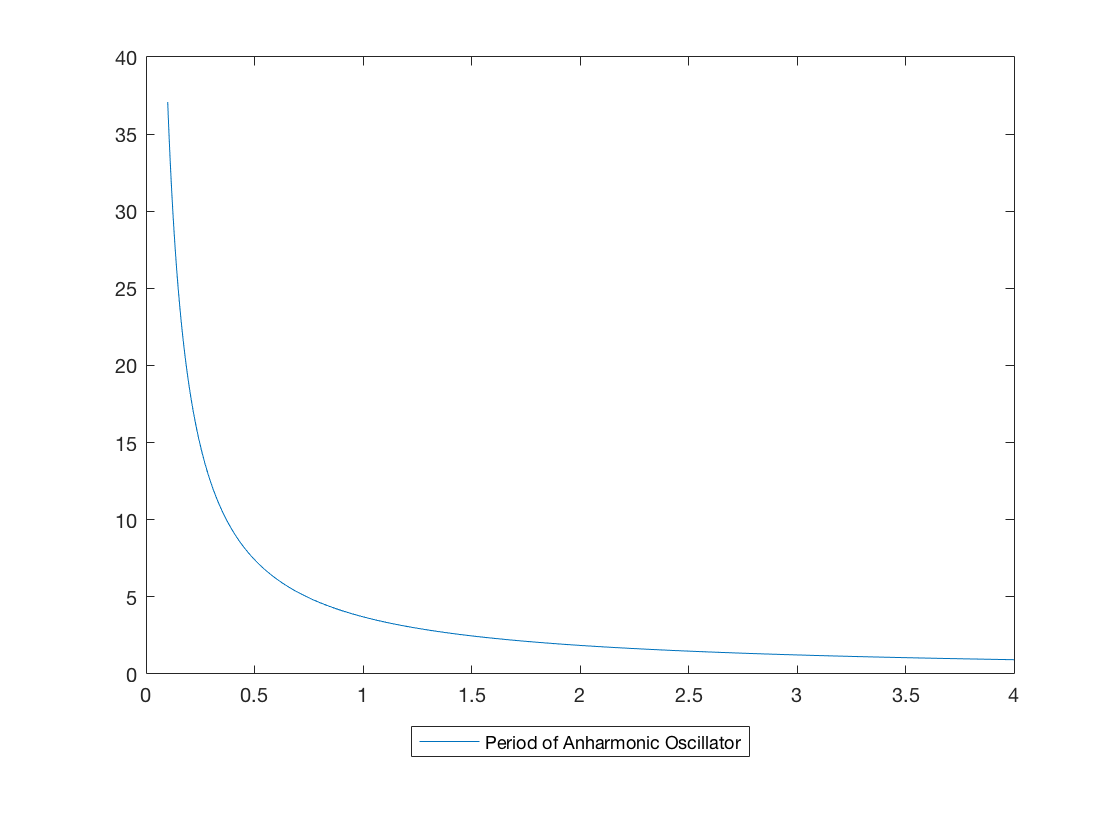

a = linspace(.1,4,1000);
Porig = @(a,x)(4./sqrt(2*(a.^4-x.^4)));% our period, the function
% create an empty array L


% but since a and x are pr 
%L = []; % or initialize an array with zeros or ones
L = zeros(1,1000);
for j = 1:1000
    variable = a(j);
    x =linspace(0,element,1000);
    Period = integral(@(x)Porig(variable,x),0,variable); % when x is = a then denominator is zero then we need to take care of the signularitie
    L(j) = Period;
end
plot (a,L)
legend('Period of Anharmonic Oscillator','Location','southoutside')

% a
% L
